## Intro

Let's take a trip down memory lane: Gradient descend optimisation algorithms. We'll do everything in MATLAB, as its been quite some time since I last touched it...

Gradient descent is by far the most common way to optimize neural networks, with every state-of-the-art Deep Learning libray containing implementations of various algorithms to optimize gradient descent. Here, we will explore the behavior of the most common algorithms, as discussed in [Ruder, Sebastian. "An overview of gradient descent optimization algorithms." arXiv preprint arXiv:1609.04747 (2016).](https://arxiv.org/pdf/1609.04747.pdf)

As best explained in the paper: Gradient descent is a way to minimize an objective function $J\left(\theta \right)$paremeterized by a model's parameters $\theta \in \Re^{d\;}$by updating the parameters in the opposite direction of the gradient of the objective function $\nabla_{\theta \;} J\left(\theta \right)$w.r.t the parameters. An equally important concept is the learning rate $\eta \;$which determined the size of the steps we take to reach a (local) minimum. In other words, we follow the direction of the slope of the surface created by the objectie function downhill until we reach a valley.

Three variants of gradient descent exist, differing in the amount of data used to compute the gradient of the objective function. These are:

- Batch (vanilla) Gradient Descent, which computes the gradient of the cost function w.r.t the parameters $\theta \;$for the entire training set,

- Stochastic Gradient Descent (SGD) that perfors a parameter update for each training example,

- and Mini-batch gradient descent, which combines the above two, by performing an update for every mini-batch of $n$ training examples.

We will have a closer look on the following gradient descent optimization algorithms:

- Stochastic Gradient Descent

- Momentum

- Nesterov Accelerated Gradient

- AdaGrad

- AdaDelta

- RMSprop

- Adam

- AdaMax

- Nadam

- AMSGrad

## Loss Surfaces

At first, we'll define some loss surfaces, purely for the purpose of visualizing the behavior of each algorithm. Let us assume that these loss surfaces correspond to the prediction error when our model is learning the training set, i.e. we will assume that $J\left(\theta \right)=\frac{1}{m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2$ (the loss function for the mean square error), is a simple 2D elliptical or the Rosenbrock or the Ackley function, which are given by the following equations:

- Sphere function: $J_1 \left(\theta_1 ,\theta_2 \right)={\left(\frac{\theta_1 }{4}\right)}^2 \;+\theta_2^{2\;}$,  $\theta_i \in \Re$ with global minimum $f\left(\theta^* \right)\approx 0$ on $\theta^* =\left(0,0\right)$

- Rosenbrock function: $J_2 \left(\theta_1 ,\theta_2 \right)=100{\left(\theta_2 -\theta_1^2 \right)}^2 +{\left(1-\theta_1 \right)}^2$, $\theta_i \in \Re$, with a global minimum $f\left(\theta^* \right)=0$on $\theta^* =\left(1,1\right)$

Let's plot these two functions, along with their minimum values:

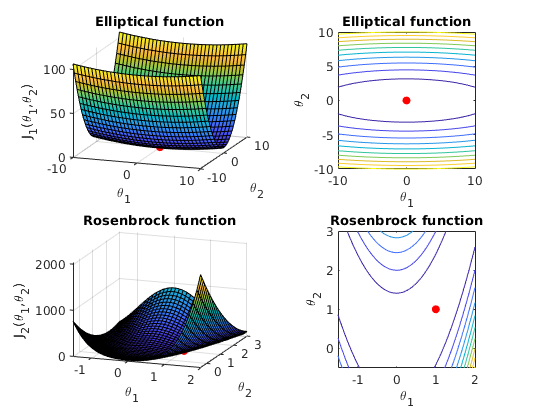

% Sphere function
J1      = @(x1, x2) (x1 / 4) .^ 2 + (x2) .^ 2;
dom_J1  = [-10 10 -10 10];

% Rosenbrock function
J2      = @(x1, x2) 100 * (x2 - x1 .^ 2) .^ 2 + (1 - x1) .^ 2;
dom_J2  = [-1.5 2 -0.5 3];


% Plot functions

h = figure;
subplot(221)
fsurf(J1, dom_J1)
view(20, 20); hold on
scatter3(0, 0, 0, 'red', 'filled')
xlabel('\theta_1'); ylabel('\theta_2'); zlabel('J_1(\theta_1,\theta_2)')
title('Elliptical function')

subplot(222)
fcontour(J1, dom_J1)
hold on
scatter(0, 0, 'red', 'filled')
xlabel('\theta_1'); ylabel('\theta_2'); zlabel('J_1(\theta_1,\theta_2)') 
title('Elliptical function'); axis equal

subplot(223)
fsurf(J2, dom_J2)
view(20, 20); hold on
scatter3(1, 1, 0, 'red', 'filled')
xlabel('\theta_1'); ylabel('\theta_2'); zlabel('J_2(\theta_1,\theta_2)') 
title('Rosenbrock function')

subplot(224)
fcontour(J2, dom_J2)
hold on
scatter(1, 1, 'red', 'filled')
xlabel('\theta_1'); ylabel('\theta_2'); zlabel('J_2(\theta_1,\theta_2)')
title('Rosenbrock function'); axis equal

For all the following, we also need to define their gradients $\nabla J\left(\theta \right)=\left(\frac{\mathrm{d}}{\mathrm{d}\theta_1 }J,\frac{\mathrm{d}}{\mathrm{d}\theta_2 }J\right)$ for they will be used in the update rules.

For the Sphere function these are: $\nabla \;J_1 =\left(\frac{\theta_1 }{2},2\theta_2 \right)$ 

For Rosenbrock, we have: $\nabla \;J_2 =\left(2\theta_1 -400\theta_1 \left(\theta_2 -\theta_1^2 \right)-2,\;200\left(\theta_2 -\theta_1^2 \right)\right)$

And their corresponding function handles are the following:

dJ1 = @(x1, x2) [x1 / 2, 2 * x2];
dJ2 = @(x1, x2) [-2 + 2 * x1 - 400 * x1 .* (x2 - x1 .^ 2), 200 * (x2 - x1 .^ 2)];

Next, we can have a look at the implementation of the algorithms, and visualize their behavior on these surfaces.

## Gradient Descent Optimisation Algorithms

### Stochastic Gradient Descent (SGD)

The parameter update at every step (or for each training example $x^{\left(i\right)}$and label $y^{\left(i\right)}$ when applied on a dataset) is performed as follows:


$$\theta_{i+1} =\theta_i -\eta \;\nabla_{\theta \;} J\left(\theta_i \right)$$


Let's see how this optimizer behaves for various learning rates. The learning rate is a critical parameter. If the learning rate is too large, we can overstep the minimum and possibly diverge. On the other hand, using too small a learning rate will require to run more iterations of gradient descent, increasing training time.

We have defined a function sgd() found in the end, that takes as inputs the loss surface gradient as a function handle, an initial point, the learning rate $\eta \;$, and a maximum number of iterations $n_{\max }$. This function will run the SGD algorithm on the chosen function, and return the entire trajectory of steps taken at every iteration until completion. Completion is defined by the following exiting criteria:

- Near-zero gradient at the new update direction, with near-zero being defined as 1e-6

- Near-zero new step, again specified as 1e-6

- Iteration limit reached.

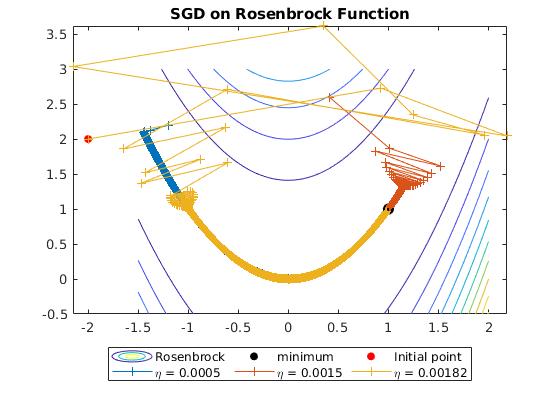

theta0 = [-2, 2];                % define starting point
etas   = [5e-4, 15e-4, 18.2e-4]; % define learning rates

% Plot function contours and minimum point
figure; fcontour(J2, dom_J2, 'DisplayName', 'Rosenbrock'); hold on
scatter(1, 1, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')

% Loop over learning rates
for eta = etas
    x = sgd(dJ2, theta0, eta); % Run SGD
    plot(x(:, 1), x(:, 2), 'marker', '+', 'DisplayName', strcat(['\eta = ', num2str(eta)])) % Plot
end

hl = legend('location', 'bestoutside', 'Orientation',"horizontal"); % Add legend
hl.NumColumns = 3;
title('SGD on Rosenbrock Function') % Add title

Indeed. the effect of learning rate is apparent. Using a very small value (blue line) results in very small steps, and the algorithm (due to the exiting criteria we have implemented) exits too early. Increasing the learning rate a bit (red line), results in bigger steps with a zig-zag pattern.

### Momentum

SGD has trouble navigating ravines, i.e. areas where the surface curves much more steeply in one dimension that in another, which tends to be common around (local or global) minima. In these scenarios, SGD oscillates across the slopes of the ravine while only making hesitant progress along the bottom towards the local optimum. This is most obvious on the red line in the previous graph. 

[Momentum](https://d1wqtxts1xzle7.cloudfront.net/55285305/momentum.pdf?1513217550=&response-content-disposition=inline%3B+filename%3DOn_the_momentum_term_in_gradient_descent.pdf&Expires=1597309251&Signature=W6fQccjWf8ERLiKxWD2RE5JHilZW3ZKfTBM4IQ2qhUMXxFrXUzDrsL1hdtk~DpBQfEL9XF9hUBh~KPhl62bgOiTl329iepXFXlAdCtganjaLFLfE63wiwwnV9QXy07EwQr7jg-9ZH3VyERsk6sI4mZdNnqj2zTiWl0tLs1c65qIiPK4WdVXtFt6ETpNyGKtZq5bSmjqS6X6hDaqKSWe9~~DYSRiij2KgdS8abFuGdk6TBAsuTsORdkXwcXIK8VE1-cSSNCAceCppuyEVUwL09Ujbc6xmOao5SuKHopF-spgXmXlf~8grjK3bJJDPeMMw-TXWREaZxSZfBwNVo~mZVw__&Key-Pair-Id=APKAJLOHF5GGSLRBV4ZA) is a method that helps accelerate the SGD in the relevant direction, and dampens oscillations. It does so by adding a fraction $\gamma \;$, called the momentum term, on the update vector of the past time step to the current update vector. The momentum term is usually set to 0.9 or a similar value.

As discussed in the paper referenced in the beginning: Essentially, when using momentum, we push a ball down a hill. The ball accumulates momentum as it rolls downhill, becoming faster and faster on the way (until it reaches its terminal velocity, if there is air resistance, i.e. γ < 1). The same thing happens to our parameter updates: The momentum term increases for dimensions whose gradients point in the same directions and reduces updates for dimensions whose gradients change directions. As a result, we gain faster convergence and reduced oscillation.

Mathematically, SGD with momentum is defined as follows:


$$\begin{array}{l}
u_{i+1} ={\gamma \;u}_i +\eta \;\nabla_{\theta \;} J\left(\theta \right)\\
\theta_{i+1} =\theta_i -u_{i+1} 
\end{array}$$
 

The corresponding function is sgd_momentum, which takes the same arguments, and same exiting criteria as before, but with the newly-defined optimizer:

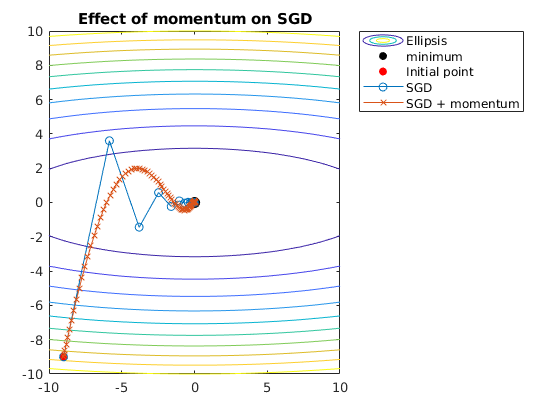

theta0 = [-9, -9];  % define starting point
eta     = 0.007;    % define learning rate
gamma   = 0.9;      % define momentum term

% Plot function contours and minimum point
figure; fcontour(J1, dom_J1, 'DisplayName', 'Ellipsis'); hold on
scatter(0, 0, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')

x2 = sgd_momentum(dJ1, theta0, eta, gamma); % SGD with momentum
x1 = sgd(dJ1, theta0, 0.7);                 % Plain SGD

% Plot results
plot(x1(:, 1), x1(:, 2), 'marker', 'o', 'DisplayName', 'SGD')
plot(x2(:, 1), x2(:, 2), 'marker', 'x', 'DisplayName', 'SGD + momentum')
legend('location', 'bestoutside', 'orientation', 'vertical');   % Add legend
title('Effect of momentum on SGD')                              % Add title
xlim(dom_J1(1:2))
ylim(dom_J1(3:4))

The advantage of SGD with momentum over plain SGD is clear. By carefully tuning the learning rate and the momentum term, the oscillations disappear, resulting in a more 'fluid' motion of the parameter updates.

### Nesterov Accelerated Gradient (NAG)

NAG augments the momentum, in the sense that our ball no longer blindly follows the slope, but it has a 'sense' of where it is going, so that it knows to slow down before the hill slopes up again. NAG offers this by using the momentum term $\gamma \;u_i$ to move the parameters $\theta$. Computing $\theta_i -\gamma \;u_i$ gives an approximation of the next position of the parameters a rough idea of where they are going to be. As such, we can now effectively look ahead by calculating the gradient not w.r.t. our current parameters, but w.r.t. the approximate future position of our parameters:


$$\begin{array}{l}
u_{i+1} ={\gamma \;u}_i +\eta \;\nabla_{\theta \;} J\left(\theta -\gamma \;u_i \right)\\
\theta_{i+1} =\theta_i -u_{i+1} 
\end{array}$$
 

The implementation is rather straightforward, with a minor modification on the sgd_momentum() function. The new function can be found in the end, as nag().

Let's compare this to the previous optimizers:

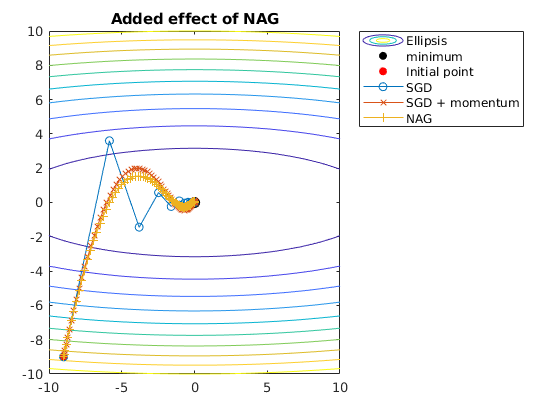

x3 = nag(dJ1, theta0, eta, gamma); % Run NAG

% Plot results
plot(x3(:, 1), x3(:, 2), 'marker', '+', 'DisplayName', 'NAG')
legend('location', 'bestoutside', 'orientation', 'vertical') % Update legend
title('Added effect of NAG')                                 % Update title

Indeed, we can see that NAG, with the same parameters as momentum SGD, first makes a big jump in the direction of the SGD + momemntum optimizer, measures the gradient and then makes a correction. This anticipatory update prevents the optimizer from going too fast and results in increased responsiveness.

### AdaGrad

[Adagrad](https://www.jmlr.org/papers/volume12/duchi11a/duchi11a.pdf?source=post_page---------------------------) takes a differenet route: It adapts the learning rate to the parameters. It performs larger updates for infrequent and smaller updates for frequent parameters, and it's been succesfully used to train large scale [neural nets for videos](http://www.wired.com/2012/06/google-x-neural-network/), and [word embeddings](https://www.aclweb.org/anthology/D14-1162.pdf), with the added benefit of not requiring a manual tune of the learning rate. Most implementations use a default value of 0.1 without any attempt to change it.

Let's see how Adagrad updates each parameter $\theta_i$ at every step $j$.  


$$\theta_{i,j+1} =\theta_{i,j} -\frac{\eta }{\sqrt{G_{i\;i,j} +\epsilon \;}}\nabla_{\theta_i } J\left(\theta_{i,j} \right)$$


where $G_{i\;i,j} \in \Re^{d\;x\;d}$ is a diagonal matrix, where each element $\left(i,i\right)$ is the sum of the squares of the gradients w.r.t. $\theta_i$, up to step $j$, while $\epsilon \;$is a smoothing term that avoids devision by zero (usually of the order of 1e-8). In a vectorized form, the update rule is the following:

$\theta_{j+1} =\theta_j -\frac{\eta }{\sqrt{G_j +\epsilon \;}}{\;\odot \nabla }_{\theta } J\left(\theta_j \right)$.

This has a more complex implementation, that can be found in the adagrad() function.

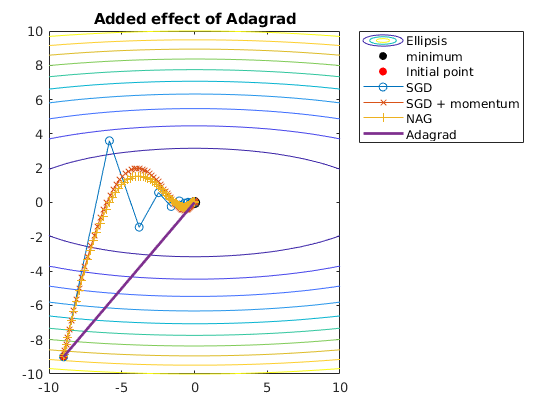

x4 = adagrad(dJ1, theta0); % Run Adagrad

% Plot results
plot(x4(:, 1), x4(:, 2), 'linewidth', 2, 'DisplayName', 'Adagrad')
legend('location', 'bestoutside', 'orientation', 'vertical') % Update legend
title('Added effect of Adagrad')                             % Update title

The superiority of Adagrad in obvious. The optimiser follows a straight line directly to the minimum, without bothering us with any manual tuning of parameters.

### AdaDelta

[AdaDelta](https://arxiv.org/pdf/1212.5701.pdf) extends Adagrad, seeking to reduce its aggressive, monotonically decreasing learning rate. These is performed by restricting the window of the accumulated past gradients to some fixed size $w$, instead of accumulating all past gradients. A further advantage of AdaDelta is that a learning rate is not required anymore, in contrast to AdaGrad which required a default learning rate.

In this method, the sum of gradients is recursively defined as a decaying average of all past square gradients. The running average $E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i$at time step $i$ depends only on the previous average and the current gradient:


$$E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i =\gamma \;E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma \right){\nabla_{\theta }^2 }_i J\left(\theta_i \right)$$


Furthermore the authors, in order to match the units in the update, they define another exponentially decaying average of the squared parameter updates:


$$E{\left\lbrack \Delta \theta^2 \right\rbrack }_i =\gamma \;E{\left\lbrack \Delta \theta^2 \right\rbrack }_{i-1} +\left(1-\gamma \right)\Delta \theta_i$$


to be used instead of the learning rate $\eta$. In this method, $\gamma \;$is set to a similar value as the momentum term, around 0.9.

Finally, the update rule becomes:


$$\theta_{i+1} =\theta_i -\frac{\sqrt{E{\left\lbrack \Delta \theta^2 \right\rbrack }_i +\epsilon \;}}{\sqrt{E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i +\epsilon \;}}\nabla_{\theta } J\left(\theta_i \right)$$


Let's have a look at the performance of AdaGrad and AdaDelta on the Rosenbrock function:

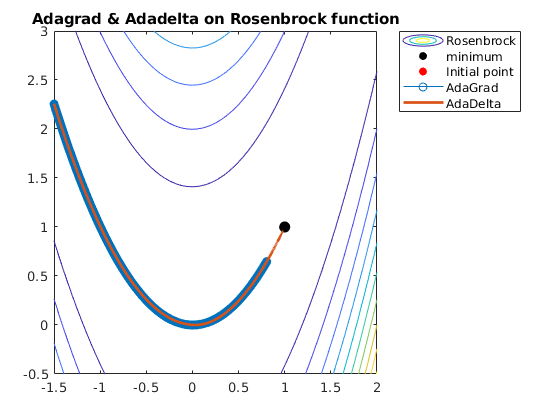

theta0 = [-2, 2]; % define starting point
gamma  = 0.9; % Exponential decaying term

x1 = adagrad(dJ2, theta0); % Run Adagrad
x2 = adadelta(dJ2, theta0, gamma); % Run Adadelta

% Plot function contours and minimum point
figure; fcontour(J2, dom_J2, 'DisplayName', 'Rosenbrock'); hold on
scatter(1, 1, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')
plot(x1(:, 1), x1(:, 2), 'marker', 'o', 'DisplayName', 'AdaGrad')
plot(x2(:, 1), x2(:, 2), 'LineWidth', 2, 'DisplayName', 'AdaDelta')
legend('location', 'bestoutside', 'orientation', 'vertical');   % Add legend
title('Adagrad & Adadelta on Rosenbrock function')              % Add title
xlim(dom_J2(1:2))
ylim(dom_J2(3:4))

Indeed, both algorithms present the same behavior, but with the same number of iterations, AdaGrad was faster in finding the optimum point. Also, from this point on we'll switch to the more challenging Ackley function, as this seems to be too easy for the optimisers.

### Adam

Adaptive Moment Estimation ([Adam](https://arxiv.org/abs/1412.6980)) also uses adaptive learning rates for each learning rate. It works like Adadelta (or RMSProp), but in addition it keeps an exponentialy decaying average of past gradients:


$$\begin{array}{l}
E{\left\lbrack \nabla_{\theta } \left(\theta \right)\right\rbrack }_i =\gamma_1 \;E{\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_1 \right){\nabla_{\theta } }_i J\left(\theta_i \right)\\
E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i =\gamma_2 \;E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_2 \right){\nabla_{\theta }^2 }_i J\left(\theta_i \right)
\end{array}$$


The authors of Adam also noted that the exponentially decaying averages of both gradients and square gradients are biased towards zero, especially during the initial time steps (they are initialized as vectors of zeros), so they proceeded in computing bias-corrected averages:


$$\begin{array}{l}
\tilde{\;E} {\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i =\frac{E{\left\lbrack \nabla_{\theta } \left(\theta \right)\right\rbrack }_i }{1-{\gamma_1 }^i }\\
\tilde{\;E} {\left\lbrack {\nabla^2 }_{\theta } J\left(\theta \right)\right\rbrack }_i =\frac{E{\left\lbrack {\nabla^2 }_{\theta } \left(\theta \right)\right\rbrack }_i }{1-{\gamma_2 }^i }
\end{array}$$


Then, these are used to update the parameters:


$$\theta_{i+1} =\theta_i -\frac{\eta }{\sqrt{\tilde{\;E} {\left\lbrack {\nabla^2 }_{\theta } J\left(\theta \right)\right\rbrack }_i \;}+\epsilon }\tilde{\;E} {\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i$$


with $\gamma_1 =0\ldotp 9$, $\gamma_2 =0\ldotp 999$, and $\epsilon ={10}^{-8}$.

This has been implemented in the adam() function. Let's see how this algorithm behaves comapred to adadelta on the Rosenbrockunction. To make it a bit more difiicult, we'll through the initial point farther away from the minimum

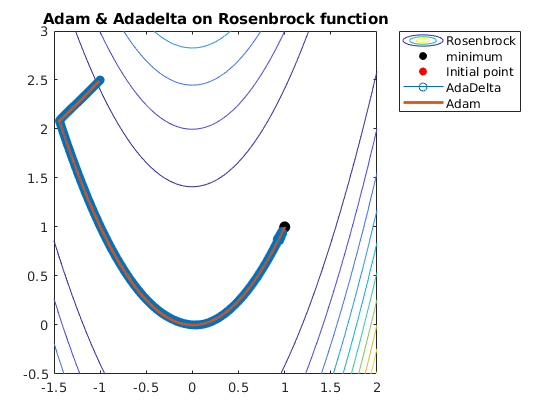

theta0 = [-1, 2.5]; % define starting point
gamma  = 0.9; % Exponential decaying term

tic
x1 = adadelta(dJ2, theta0, gamma); % Run Adadelta
dt1 = toc;

tic
x2 = adam(dJ2, theta0, 0.9, 0.999, 0.01); % Run Adam
dt2 = toc;

% Plot function contours and minimum point
figure; fcontour(J2, dom_J2, 'DisplayName', 'Rosenbrock'); hold on
scatter(1, 1, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')
plot(x1(:, 1), x1(:, 2), 'marker', 'o', 'DisplayName', 'AdaDelta')
plot(x2(:, 1), x2(:, 2), 'LineWidth', 2, 'DisplayName', 'Adam')
legend('location', 'bestoutside', 'orientation', 'vertical');   % Add legend
title('Adam & Adadelta on Rosenbrock function')                 % Add title
xlim(dom_J2(1:2))
ylim(dom_J2(3:4))

fprintf("Adadelta required %1.4f seconds", dt1)

Adadelta required 0.0816 seconds

fprintf("Adam required %1.4f seconds", dt2)

Adam required 0.0204 seconds

The behavior is similar, but the time different is quite amazing. Adam is 4x faster than Adadelta

### Adamax

Adamax is essentially a generalization of Adam (presented by the same authors), in the sense that the update rule of Adam scales inversly proportional to the $l_2$norm of the past gradients and the current gradient. This update can be generalized to the $l_P$ norm. The only essential difference is that Adam's decaying difference


$$E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i =\gamma_2 \;E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_2 \right){\nabla_{\theta }^2 }_i J\left(\theta_i \right)$$


in Adamax becomes

$E{\left\lbrack \nabla_{\theta }^p J\left(\theta \right)\right\rbrack }_i =\gamma_2^p \;E{\left\lbrack \nabla_{\theta }^p J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_2^p \right){\nabla_{\theta }^p }_i J\left(\theta_i \right)$.

Adam ($l_2$norm) is most common in practice as large values of p tend to be numerically unstable. On the other hand, the authors propse show that $l_{\infty }$does converge to a more stable rule. In that case, we can take the above equality and replace it with:

$E{\left\lbrack \nabla_{\theta }^{\infty } J\left(\theta \right)\right\rbrack }_i =\gamma_2^{\infty } \;E{\left\lbrack \nabla_{\theta }^p J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_2^{\infty } \right){\nabla_{\theta }^{\infty } }_i J\left(\theta_i \right)=\max \left(\gamma_2 E{\left\lbrack \nabla_{\theta }^{\infty } J\left(\theta \right)\right\rbrack }_{i-1} ,\left|E{\left\lbrack \nabla_{\theta } \left(\theta \right)\right\rbrack }_i \right|\right)$.

We can now plug this into the Adam update rule by simply replacing $\tilde{\;E} {\left\lbrack {\nabla^2 }_{\theta } J\left(\theta \right)\right\rbrack }_i$, with $E{\left\lbrack \nabla_{\theta }^{\infty } J\left(\theta \right)\right\rbrack }_i$. Let's see if there is any improvement in terms of time (these last algorithms already find the Rosenbrock function too easy anyway, so any improvement will manifest in time requirements only).

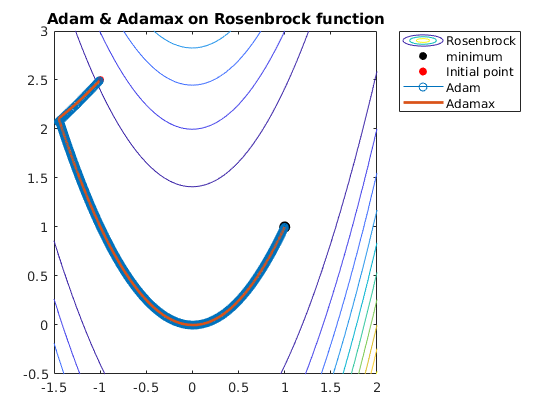

theta0 = [-1, 2.5]; % define starting point

tic
for i = 1:200
    x1 = adam(dJ2, theta0, 0.9, 0.999, 0.01); % Run Adam
end
dt1 = toc;

tic
for i = 1:200
    x2 = adamax(dJ2, theta0, 0.9, 0.999, 0.01); % Run Adamax
end
dt2 = toc;

% Plot function contours and minimum point
figure; fcontour(J2, dom_J2, 'DisplayName', 'Rosenbrock'); hold on
scatter(1, 1, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')
plot(x1(:, 1), x1(:, 2), 'marker', 'o', 'DisplayName', 'Adam')
plot(x2(:, 1), x2(:, 2), 'LineWidth', 2, 'DisplayName', 'Adamax')
legend('location', 'bestoutside', 'orientation', 'vertical');   % Add legend
title('Adam & Adamax on Rosenbrock function')              % Add title
xlim(dom_J2(1:2))
ylim(dom_J2(3:4))

fprintf("200 iterations of Adam required %1.4f seconds", dt1)

200 iterations of Adam required 2.6385 seconds

fprintf("200 iterations of Adamax required %1.4f seconds", dt2)

200 iterations of Adamax required 1.0834 seconds

Notice that the computation of the optimum was with each algorithm was repeated 200 times, so that any time-wise differences would 'register'. Adamax is twice as fast as Adam in this problem (or 8 times faster than Adadelta). Not bad at all...

### Nadam

[Nadam](https://openreview.net/pdf?id=OM0jvwB8jIp57ZJjtNEZ) is a combination of Adam and NAG (it stands for Nesterov Accelerated Adaptive Moment Estimation). In order to incorporate NAG into Adam, we need to perform a minor modification on its momentum term. In the following, the first 3 steps of Adam are repeated below, with the modifications following from step 4 onwards:

From Adam:


$$\begin{array}{l}
E{\left\lbrack \nabla_{\theta } \left(\theta \right)\right\rbrack }_i =\gamma_1 \;E{\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_1 \right){\nabla_{\theta } }_i J\left(\theta_i \right)\\
E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_i =\gamma_2 \;E{\left\lbrack \nabla_{\theta }^2 J\left(\theta \right)\right\rbrack }_{i-1} +\left(1-\gamma_2 \right){\nabla_{\theta }^2 }_i J\left(\theta_i \right)
\end{array}$$



$$\tilde{\;E} {\left\lbrack {\nabla^2 }_{\theta } J\left(\theta \right)\right\rbrack }_i =\frac{E{\left\lbrack {\nabla^2 }_{\theta } \left(\theta \right)\right\rbrack }_i }{1-{\gamma_2 }^i }$$


Modifications / additions for Nadam:


$$\tilde{\;E} {\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i =\frac{E{\left\lbrack \nabla_{\theta } \left(\theta \right)\right\rbrack }_i }{1-{\gamma_1 }^{i+1} }$$



$$\tilde{\;E} {{{\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i }^{\prime } }^{\prime } =\gamma_1 \tilde{\;E} {\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i +\frac{\left(1-\gamma_1 \right){\nabla_{\theta } }_i J\left(\theta_i \right)}{1-{\gamma_1 }^i }$$



$$\theta_{i+1} =\theta_i -\frac{\eta }{\sqrt{\tilde{\;E} {\left\lbrack {\nabla^2 }_{\theta } J\left(\theta \right)\right\rbrack }_i \;}+\epsilon }\tilde{\;E} {{{\left\lbrack \nabla_{\theta } J\left(\theta \right)\right\rbrack }_i }^{\prime } }^{\prime }$$


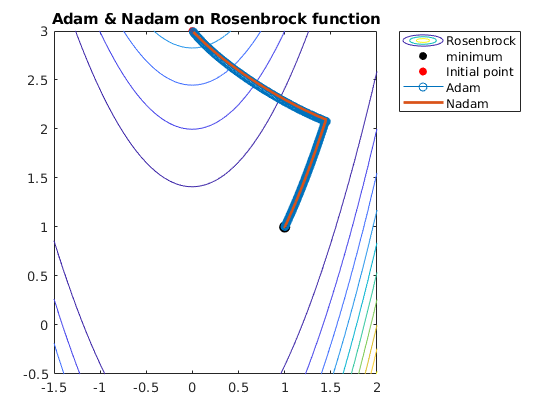

theta0 = [0, 3]; % define starting point
gamma  = 0.9; % Exponential decaying term

tic
for i = 1:200
    x1 = adam(dJ2, theta0, 0.9, 0.999, 0.01); % Run Adam
end
dt1 = toc;

tic
for i = 1:200
    x2 = nadam(dJ2, theta0, 0.9, 0.999, 0.01); % Run Nadam
end
dt2 = toc;

% Plot function contours and minimum point
figure; fcontour(J2, dom_J2, 'DisplayName', 'Rosenbrock'); hold on
scatter(1, 1, 70, 'black', 'filled', 'DisplayName', 'minimum')
scatter(theta0(1), theta0(2), 'red', 'filled', 'DisplayName', 'Initial point')
plot(x1(:, 1), x1(:, 2), 'marker', 'o', 'DisplayName', 'Adam')
plot(x2(:, 1), x2(:, 2), 'LineWidth', 2, 'DisplayName', 'Nadam')
legend('location', 'bestoutside', 'orientation', 'vertical');   % Add legend
title('Adam & Nadam on Rosenbrock function')              % Add title
xlim(dom_J2(1:2))
ylim(dom_J2(3:4))

fprintf("200 iterations of Adam required %1.4f seconds", dt1)

200 iterations of Adam required 3.1929 seconds

fprintf("200 iterations of Nadam required %1.4f seconds", dt2)

200 iterations of Nadam required 2.5543 seconds

## Conclusions

The points that should be taken from all these implementations are best described on the paper who performed this comparison:

"you [are] likely achieve the best results using one of the adaptive learning-rate methods. An additional benefit is that you will not need to tune the learning rate but will likely achieve the best results with the default value."

In summary, RMSprop is an extension of Adagrad that deals with its radically diminishing learning rates. It is identical to Adadelta, except that Adadelta uses the RMS of parameter updates in the numerator update rule. Adam, finally, adds bias-correction and momentum to RMSprop. Insofar, RMSprop, Adadelta, and Adam are very similar algorithms that do well in similar circumstances. This bias-correction helps Adam slightly outperform RMSprop towards the end of optimization as gradients become sparser. Insofar, *Adam might be the best overall choice*.

## Function definitions

### SGD

function theta_traj = sgd(dJ, theta_0, eta)
% Stochastic Gradient Descend on junction J, with gradient dJ, 
% starting at theta_0, with learning rate eta

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));

    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e3;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, numel(theta_0));
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0; 
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        g         = grad(theta);            % calculate gradient
        theta_new = theta - eta * g;        % take step
        theta_traj(niter + 1, :) = theta;   % Append current step to matrix
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
    end
end


### SGD with momentum


function theta_traj = sgd_momentum(dJ, theta_0, eta, gamma)
% Stochastic Gradient Descend with momentum on junction J, with gradient dJ, 
% starting at theta_0, with learning rate eta

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));

    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e3;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, numel(theta_0));
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0; u_pre = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        g         = grad(theta);            % calculate gradient
        u         = gamma * u_pre + eta * g;
        theta_new = theta - u;              % take step
        theta_traj(niter + 1, :) = theta;   % Append current step to matrix
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new; u_pre = u;
    end
end

function theta_traj = nag(dJ, theta_0, eta, gamma)
% Nesterov Accelerated Gradient on junction J, with gradient dJ, 
% starting at theta_0, with learning rate eta

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));

    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e3;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, numel(theta_0));
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0; u_pre = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        g         = grad(theta - gamma * u_pre); % calculate gradient
        u         = gamma * u_pre + eta * g;
        theta_new = theta - u;              % take step
        theta_traj(niter + 1, :) = theta;   % Append current step to matrix
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new; u_pre = u;
    end
end


### AdaGrad

function theta_traj = adagrad(dJ, theta_0)
% Adagrad on junction J, with gradient dJ, 
% starting at theta_0

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));
    
    % define epsilon
    epsilon = sqrt(eps);
    
    % define number of parameters
    npar = numel(theta_0);
    
    % define (default) eta
    eta = 0.1;
    
    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e4;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, npar);
    
    % Initialise matrix to hold past gradients
    past_grad = zeros(1, npar);
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        % compute gradient
        g = grad(theta);
        
        % update past gradient matrix
        past_grad = past_grad + g .^ 2;
        
        % take step
        theta_new = theta - eta .* g ./ (sqrt(past_grad) + epsilon);
        
        % Append current step to matrix
        theta_traj(niter + 1, :) = theta;
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
    end
end


### AdaDelta

function theta_traj = adadelta(dJ, theta_0, gamma)
% AdaDelta on junction J, with gradient dJ, 
% starting at theta_0, with decay fraction gamma

    % define number of parameters
    npar = numel(theta_0);

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));
    
    % define epsilon
    epsilon = sqrt(eps);
    
    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e4;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, npar);
    
    % Initialise matrices to hold accumulated gradients and updates
    acc_grad  = zeros(1, npar); % accumulated gradients
    acc_theta = zeros(1, npar); % accumulated updates
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        % calculate gradient
        g = grad(theta);
        
        % update gradient matrix
        acc_grad = gamma .* acc_grad + (1 - gamma) .* g .^ 2; 
        
        % compute update
        dtheta = - sqrt(acc_theta + epsilon) ./ sqrt(acc_grad + epsilon) .* g;
        
        % update accumulated theta matrix
        acc_theta = gamma .* acc_theta + (1 - gamma) .* dtheta .^ 2;
        
        % take step
        theta_new = theta + dtheta;        
        
        % Append current step to matrix
        theta_traj(niter + 1, :) = theta;   
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
    end
end


### Adam

function theta_traj = adam(dJ, theta_0, gamma1, gamma2, eta)
% Adam on junction J, with gradient dJ, starting at theta_0, 
% % with decay fractions gamma1, gamma2 and learning rate eta

    % define number of parameters
    npar = numel(theta_0);

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));
    
    % define epsilon
    epsilon = 1e-8;
    
    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e4;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, npar);
    
    % Initialise matrices to hold accumulated gradients and updates
    acc_grad   = zeros(1, npar); % accumulated gradients
    acc_grad2  = zeros(1, npar); % accumulated updates
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        % calculate gradient
        g = grad(theta);
        
        % update gradient matrices
        acc_grad  = gamma1 .* acc_grad + (1 - gamma1) .* g;
        acc_grad2 = gamma2 .* acc_grad2 + (1 - gamma2) .* g .^ 2;
        
        % Compute bias-corrected updates
        acc_grad_hat  = acc_grad ./ (1 - gamma1 ^ (niter + 1));
        acc_grad2_hat = acc_grad2 ./ (1 - gamma2 ^ (niter + 1));
        
        % take step
        theta_new = theta - eta .* acc_grad_hat ./ (sqrt(acc_grad2_hat) + epsilon);        
        
        % Append current step to matrix
        theta_traj(niter + 1, :) = theta_new;   
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
    end
end


### Adamax

function theta_traj = adamax(dJ, theta_0, gamma1, gamma2, eta)
% Adam on junction J, with gradient dJ, starting at theta_0, 
% % with decay fractions gamma1, gamma2 and learning rate eta

    % define number of parameters
    npar = numel(theta_0);

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));
        
    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e4;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, npar);
    
    % Initialise matrices to hold accumulated gradients and updates
    acc_grad   = zeros(1, npar); % accumulated gradients
    acc_norm  = zeros(1, npar); % accumulated updates
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        % calculate gradient
        g = grad(theta);
        
        % update gradient matrix
        acc_grad  = gamma1 .* acc_grad + (1 - gamma1) .* g;
        
        % Update the exponentially weighted infinity norm
        acc_norm = max(gamma2 .* acc_norm, abs(g));
        
         % Compute bias-corrected update
        acc_grad_hat  = acc_grad ./ (1 - gamma1 ^ (niter + 1));
        
        % take step
        theta_new = theta - eta .* acc_grad_hat ./ acc_norm;        
        
        % Append current step to matrix
        theta_traj(niter + 1, :) = theta_new;   
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
        
    end
end

### Nadam

function theta_traj = nadam(dJ, theta_0, gamma1, gamma2, eta)
% Adam on junction J, with gradient dJ, starting at theta_0, 
% % with decay fractions gamma1, gamma2 and learning rate eta

    % define number of parameters
    npar = numel(theta_0);

    % redefine function syntax for use with optimization
    grad = @(theta) dJ(theta(1), theta(2));
    
    % define epsilon
    epsilon = 1e-8;
    
    % define termination criteria
    tol     = 1e-6; % termination tolerance
    maxiter = 5e4;  % maximum number of allowed iterations
    
    % Initialize matrix to hold the steps taken
    theta_traj = NaN(maxiter + 1, npar);
    
    % Initialise matrices to hold accumulated gradients and updates
    acc_grad   = zeros(1, npar); % accumulated gradients
    acc_grad2  = zeros(1, npar); % accumulated updates
    
    % initialize gradient norm, optimization vector, iteration counter
    gnorm = inf; theta = theta_0; niter = 0;
    
    % run gradient descent algorithm
    while gnorm >= tol && niter <= maxiter
        
        % calculate gradient
        g = grad(theta);
        
        % update gradient matrices
        acc_grad  = gamma1 .* acc_grad + (1 - gamma1) .* g;
        acc_grad2 = gamma2 .* acc_grad2 + (1 - gamma2) .* g .^ 2;
        
        % Compute bias-corrected updates
        acc_grad_hat  = acc_grad ./ (1 - gamma1 ^ (niter + 2));
        acc_grad2_hat = acc_grad2 ./ (1 - gamma2 ^ (niter + 1));
        
        % NAG
        acc_grad_hat_dot = gamma1 * acc_grad_hat + (((1 - gamma1) * g) ./ (1 - gamma1 .^ (niter + 2)));
        
        % take step
        theta_new = theta - eta .* acc_grad_hat_dot ./ (sqrt(acc_grad2_hat) + epsilon);        
        
        % Append current step to matrix
        theta_traj(niter + 1, :) = theta_new;   
        
        % update termination metrics
        niter = niter + 1; gnorm = norm(g); theta = theta_new;
    end
end
